# Exploring the Experiment's Design

In this set of exercises, we'll get our first look at the experiment we'll be analyzing in this course; curated data from the [Steinmetz et al, 2019](https://www.nature.com/articles/s41586-019-1787-x) paper.

Today's data is focused on three CSV files, each containing sessions  from a different stretch of data collection.  They contain trial-level  data from the experiment:

- steinmetz_winter2016.csv

- steinmetz_summer2017.csv

- steinmetz_winter2017.csv

## Loading and viewing data

Let's load in some csv data with MATLAB and see what we have!

**Download datafiles**

userpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "src"))
download_from_sciebo("https://uni-bonn.sciebo.de/s/QyHoxfrSF6JILQd", 'data/steinmetz_winter2016.csv')

Done!

download_from_sciebo("https://uni-bonn.sciebo.de/s/Z3QHxJztEueDQF8", 'data/steinmetz_summer2017.csv')

Done!

download_from_sciebo("https://uni-bonn.sciebo.de/s/9FxelLhARmHpw85", 'data/steinmetz_winter2017.csv')

Done!

userpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "data"))

**Example: **

Load in the winter 2016 dataset and view the first 5 rows of the data

data_winter2016 = readtable('data/steinmetz_winter2016.csv');
data_winter2016(1:5,:)

ans = 5×15 table
    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_time    reaction_type     mouse      session_date    session_id
    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    _____________    ________    ____________    __________

    

The variable data is a MATLAB table, we can see that in the Workspace pannel on the right.

**Exercises**

Load in the summer 2017 dataset and view the first 10 rows of the data

ans = 10×15 table
    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_time    reaction_type      mouse      session_date    session_id
    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    _____________    _________    ____________    __________

 

How many rows are in the summer 2017 dataset?

How many columns are in the summer 2017 dataset?

ans = 2747

What are the column names in the summer 2017 dataset?

ans = 15

Load in the winter 2017 dataset to an appropriately named variable

How many rows are in the winter 2017 dataset?

ans = 1×15 cell array
    {'trial'}    {'active_trials'}    {'contrast_left'}    {'contrast_right'}    {'stim_onset'}    {'gocue_time'}    {'response_type'}    {'response_time'}    {'feedback_time'}    {'feedback_type'}    {'reaction_time'}    {'reaction_type'}    {'mouse'}    {'session_date'}    {'session_id'}


Combine the 3 datasets into one table named `data`

How many trials are there in the combined dataset?

ans = 7906

Are you sure that the combined dataset has all the rows of the 3 smaller datasets? 

Count the rows in each to find out.

ans = 14420

## Experiment Description: Calculating Statistics on Continuous Data

Let's calculate some simple statistics from the dataset.

**Example**

Find the minimum response time in the data

min(data.response_time)

**Exercises**

Find the maximum response time in the data

ans = logical
   1


Find the maximum gocue time in the data

Find the minimum gocue time in the data

Find the mean response time in the data. **Hint** - as the data contains missing values use the "omitmissing" option.

Calculate the mean of response time including missing values. How do missing values affect the result?

ans = 0.4794

Find the median response time in the data

Find the standard deviation of response time

ans = 2.7136

Find the standard deviation of gocue time

ans = 1.1988

Find the range of gocue time 

Find the range of feedback time using the `max()` and `min()` functions

ans = 0.3951

ans = 1.4228

ans = NaN

## Experiment Description: Calculating Statistics of Across Categorical Data

In data  science we often want to perform analysis on distinct separate categories, for example, analysing trials that occured on different days. 

To do this, we group the data and analyse each group separately.

**Example Exercise**

How many trials occurred for each session date?

groupsummary(data,"session_date")

ans = 1.1833

**Exercises**

How many trials did each mouse participate in?

ans = 0.6614

What was the mean response time for each mouse?

ans = 0.2005

What was the minimum response time for each mouse?

What was the most common (ie. mode) reaction_type for each mouse?

ans = 0.8038

What was the range of response times for each session date?

ans = 2.2438

Rerun the last exercise replaceing "range" with "all"

What was the largest number of trials that any mouse took part in? **Hint **- the `groupsummary` function returns a table, from which you can perform compuations on 

How many trials did each mouse take part in on each session date?

What was the average number of trials that each mouse participated in in a session? 

ans = 31×2 table
    session_date    GroupCount
    ____________    __________

    14-Dec-2016        364    
    17-Dec-2016        401    
    18-Dec-2016        378    
    07-Jan-2017        554    
    08-Jan-2017        632    
    09-Jan-2017        585    
    10-Jan-2017        363    
    11-Jan-2017        252    
    12-Jan-2017        238    
    15-May-2017        357    
    16-May-2017        345    
    18-May-2017        194    
    15-Jun-2017        360    
    16-Jun-2017        482    
    17-Jun-2017        557    
    18-Jun-2017        452    


## Visualizing the Experimental Design using Plots

**Example Exercise**

Make a bar plot showing how many times each response type appeared in the data

response_type_count = groupsummary(data, "response_type");
bar(response_type_count.response_type, response_type_count.GroupCount)
xlabel('response type')

ans = 10×2 table
        mouse        GroupCount
    _____________    __________

    {'Cori'     }       1143   
    {'Forssmann'}       1485   
    {'Hench'    }       1851   
    {'Lederberg'}       2902   
    {'Moniz'    }        896   
    {'Muller'   }       1112   
    {'Radnitz'  }       1512   
    {'Richards' }       1677   
    {'Tatum'    }       1389   
    {'Theiler'  }        453   


**Exercises**

Plot the counts of feedback type from the dataset as a bar plot

ans = 10×3 table
        mouse        GroupCount    mean_response_time
    _____________    __________    __________________

    {'Cori'     }       1143             1.5909      
    {'Forssmann'}       1485             1.4706      
    {'Hench'    }       1851             1.5257      
    {'Lederberg'}       2902             1.1438      
    {'Moniz'    }        896             1.7777      
    {'Muller'   }       1112             1.5758      
    {'Radnitz'  }       1512             1.5591      
    {'Richards' }       1677             1.3583      
    {'Tatum'    }       1389             1.3377      
    {'Theiler'  }        453             1.3388      


Make a bar plot showing the frequency of each `contrast_left` value with red bars

ans = 10×3 table
        mouse        GroupCount    min_response_time
    _____________    __________    _________________

    {'Cori'     }       1143            0.56821     
    {'Forssmann'}       1485            0.49491     
    {'Hench'    }       1851            0.55218     
    {'Lederberg'}       2902            0.47941     
    {'Moniz'    }        896            0.68261     
    {'Muller'   }       1112             0.5854     
    {'Radnitz'  }       1512            0.58381     
    {'Richards' }       1677            0.50589     
    {'Tatum'    }       1389            0.51359     
    {'Theiler'  }        453            0.48259     


Make a bar plot showing how many trials each mouse participated in

Recreate the above bar plot, but sorting the bars from smallest to largest. 

ans = 10×3 table
        mouse        GroupCount    mode_reaction_type
    _____________    __________    __________________

    {'Cori'     }       1143                1        
    {'Forssmann'}       1485               -1        
    {'Hench'    }       1851                1        
    {'Lederberg'}       2902               -1        
    {'Moniz'    }        896               -1        
    {'Muller'   }       1112                1        
    {'Radnitz'  }       1512               -1        
    {'Richards' }       1677                0        
    {'Tatum'    }       1389                1        
    {'Theiler'  }        453               -1        


Add an appropriate y label to your plot

ans = 31×3 table
    session_date    GroupCount    range_response_time
    ____________    __________    ___________________

    14-Dec-2016        364              2.1054       
    17-Dec-2016        401              2.1227       
    18-Dec-2016        378              2.1076       
    07-Jan-2017        554              2.1245       
    08-Jan-2017        632              2.1158       
    09-Jan-2017        585              2.0917       
    10-Jan-2017        363              2.0796       
    11-Jan-2017        252              2.0306       
    12-Jan-2017        238              1.9787       
    15-May-2017        357              1.9979       
    16-May-2017        345              1.9422       
    18-May-2017        194              2.0036       
    15-Jun-2017        360              2.1031       
    16-Jun-2017        482              2.1031       
    17-Jun-2017 

Make a swarmchart showing the response time distributions for each mouse. **Hint** - the x data inputted to swarmchart must be categorical data 

ans = 31×14 table
    session_date    GroupCount    mean_response_time    sum_response_time    min_response_time    max_response_time    range_response_time    median_response_time    mode_response_time    var_response_time    std_response_time    nummissing_response_time    nnz_response_time    numunique_response_time
    ____________    __________    __________________    _________________    _________________    _________________    ___________________    ____________________    __________________    _________________    _________________    ________________

## Demo: a 3D bar plot

The following code makes a 3D bar plot showing how many trials each mouse underwent on each session date for the summer 2017 dataset.

mouse_names =unique(data.mouse); % get all mouse names
session_dates = unique(data.session_date); % get all session dates

ans = 2902


% calculate number of trials for each combination of mouse and session date
mouse_session_counts=groupcounts(data,["mouse","session_date"], "IncludeEmptyGroups",true)

ans = 39×3 table
        mouse        session_date    GroupCount
    _____________    ____________    __________

    {'Cori'     }    14-Dec-2016        364    
    {'Cori'     }    17-Dec-2016        401    
    {'Cori'     }    18-Dec-2016        378    
    {'Forssmann'}    01-Nov-2017        359    
    {'Forssmann'}    02-Nov-2017        364    
    {'Forssmann'}    04-Nov-2017        400    
    {'Forssmann'}    05-Nov-2017        362    
    {'Hench'    }    15-Jun-2017        360    
    {'Hench'    }    16-Jun-2017        482    
    {'Hench'    }    17-Jun-2017        557    
    {'Hench'    }    18-Jun-2017        452    
    {'Lederberg'}    05-Dec-2017        450    
    {'Lederberg'}    06-Dec-2017        410    
    {'Lederberg'}    07-Dec-2017        378    
    {'Lederberg'}    08-Dec-2017        514    
    {'Lederberg'}    09-Dec-2017        390    


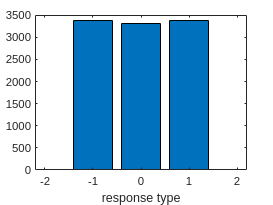

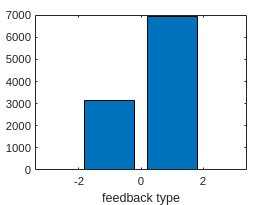

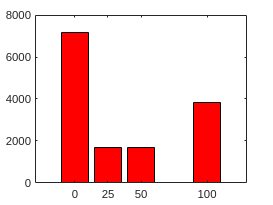

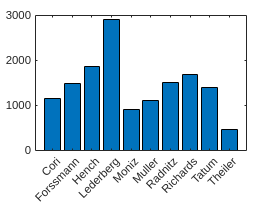

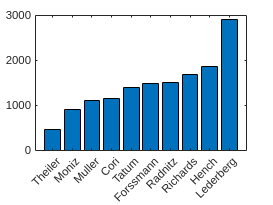

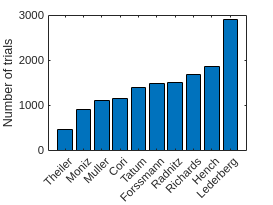

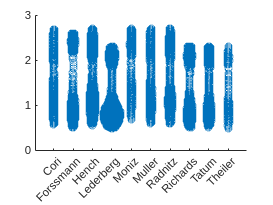

mouse_session_counts = 310×4 table
     mouse      session_date    GroupCount    Percent
    ________    ____________    __________    _______

    {'Cori'}    14-Dec-2016        364        2.5243 
    {'Cori'}    17-Dec-2016        401        2.7809 
    {'Cori'}    18-Dec-2016        378        2.6214 
    {'Cori'}    07-Jan-2017          0             0 
    {'Cori'}    08-Jan-2017          0             0 
    {'Cori'}    09-Jan-2017          0             0 
    {'Cori'}    10-Jan-2017          0             0 
    {'Cori'}    11-Jan-2017          0             0 
    {'Cori'}    12-Jan-2017          0             0 
    {'Cori'}    15-May-2017          0             0 
    {'Cori'}    16-May-2017          0             0 
    {'Cori'}    18-May-2017          0             0 
    {'Cori'}    15-Jun-2017          0             0 
    {'Cori'}    16

reshaped_data_for_plot =    364     0     0     0     0     0     0     0     0     0     0     0   514     0     0     0   297     0     0   371     0     0     0     0     0     0     0     0     0     0     0
   401     0     0     0     0   359     0     0     0     0     0     0   390     0     0     0     0     0     0   288     0     0     0     0     0     0     0     0     0     0     0
   378     0     0     0     0   364     0     0     0     0     0     0   334     0     0     0     0     0     0   363     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0   400     0     0     0     0     0     0   426   357     0     0     0     0     0   252     0     0     0     0     0     0     0   421     0     0     0
     0     0     0     0     0   362     0   360     0     0     0     0     0   345     0     0     0     0     0   238     0     0     0   253     0     0     0   368     0     0     0
     0     0     0     0     0     0    

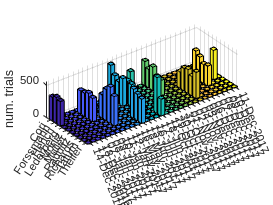

% reshape the results into a matrix
reshaped_data_for_plot = reshape(mouse_session_counts.GroupCount, length(mouse_names),length(session_dates))
% make barplot
bar3(reshaped_data_for_plot)

%format the plot
yticklabels(mouse_names)
xticks([1:1: length(session_dates)])
xticklabels(datestr(session_dates))
zlabel('num. trials')